# Running Python with MATLAB

## Call Python from MATLAB

### Option 1: Setup a Python Environment

Check which version of Python is installed and that it is on your MATLAB path. if running on matlab online, a version of Python is already installed on the MathWorks' servers.

py = pyenv % or pyenv()

if py.Version == ""
    disp "Python not installed"
end

If multiple versions of Python are detected or installed on your computer, specify the version of Python you want to run:

%pyenv(Version="3.11");

If you downloaded a Python interpreter, but did not register it in the Windows registry, use:

Check to see if your environment is initialized. Did you receive an error? Are all of your Python libraries installed?

% Calculate the square root of 42 using Python
result = pyrun("import math; sqrt_value = math.sqrt(42); sqrt_value", "sqrt_value");

Once your Python Environment (pyenv) is initialized, try this:

% Type your python code here


Did your code run? What happened? What do you need to change? What inputs do you have to specify?

% SPOILER ALERT: you have to specify which variable you want it to return
% back to MATLAB
% result = pyrun("import math; sqrt_value = math.sqrt(75); sqrt_value", "sqrt_value");

### Option 2: Use the Python Live Task

Navigate to your toolstrip and select the Live Editor tab. In the Code section, select Task. Search for and select "Run Python Code".

% Python code input
pycode = [...
"##math.sqrt(42)",...
"",...
"import math as math",...
"math.sqrt(42)",...
"print(math.sqrt(42))",...
"mm = math.sqrt(42)"...
];

try
    [mm] = pyrun(pycode, ...
         [ "mm" ])
catch ME
    % Clear temporary variables from workspace and from Python
    clear pycode;
    rethrow(ME)
end

% Clear temporary variables from workspace and from Python
clear pycode;

### Export MATLAB as...

In the toolstrip, navigate to Live Editor > Export > Export to...

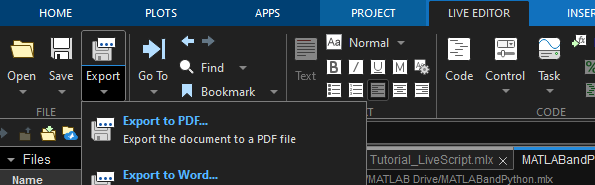

### Compile MATLAB Code as a Standalone Executable or as Python Code

(not available in online version)

In the toolstrip, navigate to Apps > Standalone Application Compiler.

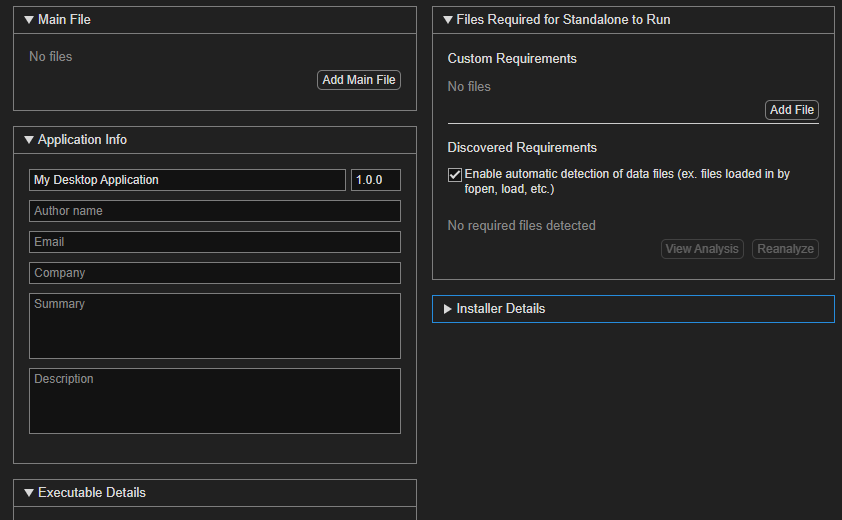

Example: sunpy.mlapp

open sunpy.mlapp
sunpy

## Call MATLAB from Python

[MATLAB Engine for Python](https://pypi.org/project/matlabengine/) - make sure you download the version that's compatible with the version of MATLAB you're using!

[Call MATLAB from Python](matlab:open('.\CallMATLABfromPython\CallMATLABfromPython.ipynb')) - MATLAB can read ipynb files, but let's open in this in another IDE of your choice.

*© The MathWorks, Inc. 2025*